clc
clear all
close all;

X = [ 0 0 1;
      0 1 1;
      1 0 1;
      1 1 1;
    ];
 
D = [ 0
      0
      1
      1
    ];
 
 
E1 = zeros(1000, 1);
E2 = zeros(1000, 1);
 
W1 = 2*rand(1, 3) - 1

W1 =     0.4121   -0.9363   -0.4462


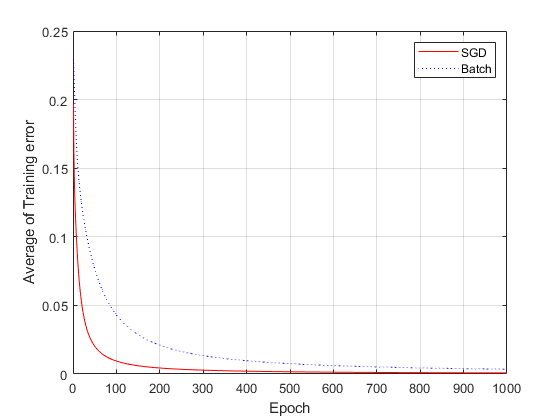

W2 = W1;
 
for epoch = 1:1000           % train
  alpha = 0.9;
  
  N = 4;  
  for k = 1:N
    x = X(k, :)';
    d = D(k);
 
    v = W1*x;
    y = Sigmoid(v);
    
    e     = d - y;  
    delta = y*(1-y)*e;
  
    dW = alpha*delta*x;     % delta rule    
    
    W1(1) = W1(1) + dW(1); 
    W1(2) = W1(2) + dW(2);
    W1(3) = W1(3) + dW(3);    
  end
%SGD END
 
  alpha = 0.9;
 
  dWsum = zeros(3, 1);
   
  N = 4;  
  for k = 1:N
    x = X(k, :)';
    d = D(k);
                        
    v = W2*x;
    y = Sigmoid(v);
    
    e     = d - y;    
    delta = y*(1-y)*e;
    
    dW = alpha*delta*x;
    
    dWsum = dWsum + dW;
  end
  dWavg = dWsum / N;
  
  W2(1) = W2(1) + dWavg(1);
  W2(2) = W2(2) + dWavg(2);
  W2(3) = W2(3) + dWavg(3);
 
 
  es1 = 0;
  es2 = 0;
  N   = 4;
  for k = 1:N
    x = X(k, :)';
    d = D(k);
    
    v1  = W1*x;
    y1  = Sigmoid(v1);
    es1 = es1 + (d - y1)^2;
    
    v2  = W2*x;
    y2  = Sigmoid(v2);
    es2 = es2 + (d - y2)^2;
  end
  E1(epoch) = es1 / N;
  E2(epoch) = es2 / N;
end
 
plot(E1, 'r')
hold on
plot(E2, 'b:')
xlabel('Epoch')
ylabel('Average of Training error')
legend('SGD', 'Batch')
grid on

function y = Sigmoid(x)
  y = 1 ./ (1 + exp(-x));
end
